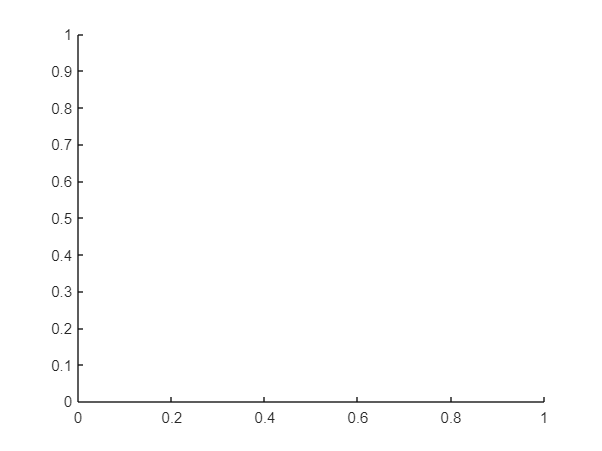

clear all
turn_pts = 20;
trains = 2;
tracks = 5;
figure; hold on

for train = 1:trains
    track = [round(tracks/2) zeros(1,turn_pts)];
    for turn_pt = 2:turn_pts+1
        if track(turn_pt - 1) == 1
            track(turn_pt) = track(turn_pt - 1) + randi(2) - 1; % 0/+1
        elseif track(turn_pt - 1) == tracks
            track(turn_pt) = track(turn_pt - 1) + randi(2) - 2; % -1/0
        else
            track(turn_pt) = track(turn_pt - 1) + randi(3) - 2; % -1/0/+1
        end
    end
    plot(0:turn_pts,track,'O-')
end
yticks(1:tracks)
xlabel('Turn Points')
ylabel('Track Position')
hold off
